# 1) Model architecture

[-> go back to starting page](matlab:open('./StartingPage.mlx'))

## High level overview of SEPIC model structure

You can open the main model from the Project Shortcut tab, under the section "General":

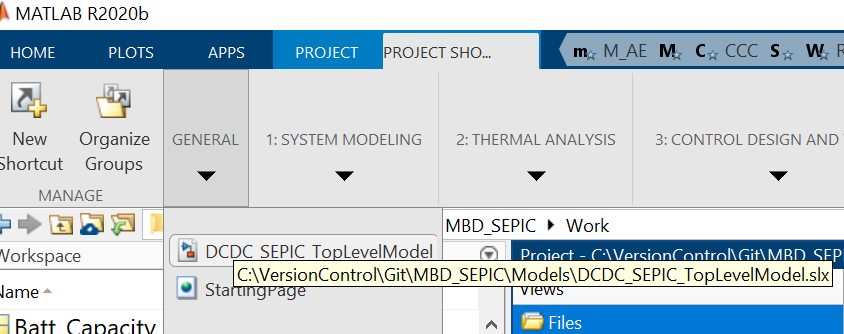

Or run this command:

open_system('DCDC_SEPIC_TopLevelModel.slx');

The following model opens: you can use the blue hyperlinks (which are linked to MATLAB code in this case) to activate the correct variants and simulation mode depending on which scenario you are looking to run. Up until number 3 (SIL) you can perform it without hardware. Point (4) needs a TI C2000 development board connected to the host PC (usually using an USB cable). Point (5) requires the actual demo kit with LEDs.

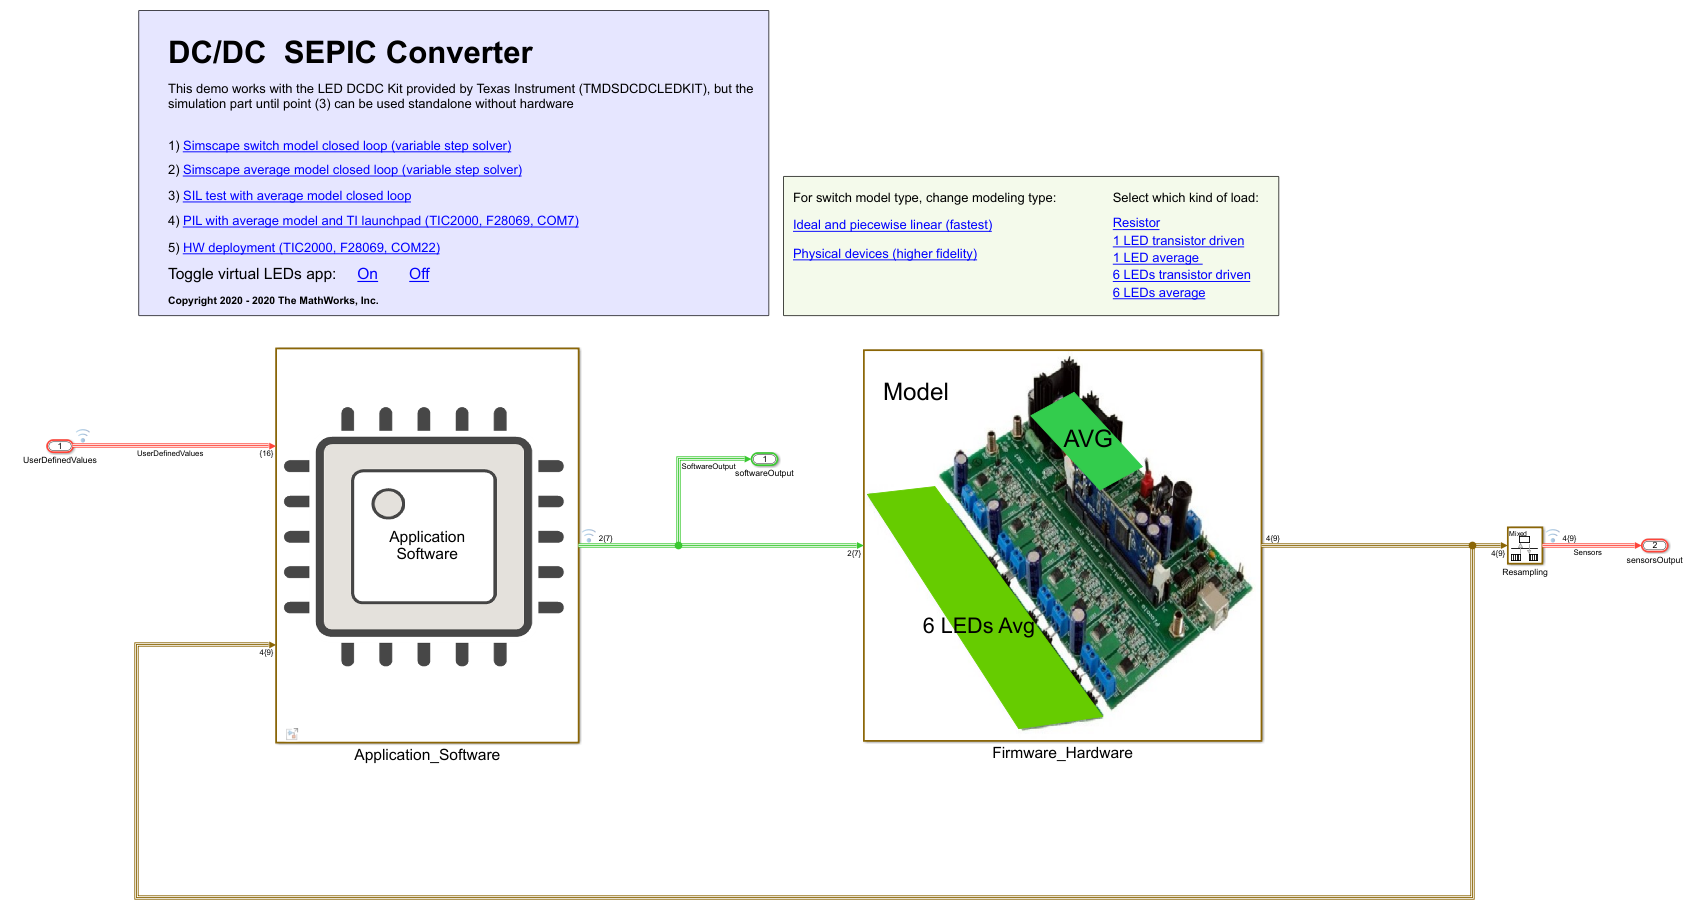

## Cool technologies used

Below find helpful links to some cool technologies we used to put together the entire model

### Variant subsystems

As you may have noticed by clicking on various hyperlink, we can switch the active variants. Some examples are the plant model level of fidelity (eg switched model - slower but more accurate - vs average model, faster but without switching dynamics), or activate the IO block in the case of the hardware deployment. More information here:

[https://ch.mathworks.com/help/simulink/ug/variant-subsystems.html](https://ch.mathworks.com/help/simulink/ug/variant-subsystems.html)

### Software and Processor - in - the - Loop (SIL/PIL)

Points (3) and (4) use the Embedded Coder infrastructure to actually run the generated code instead of the Simulink Model for the subsystem "Application_Software". SIL will connect to the C-code running on the host machine, while PIL will execute the code on the target development board. More information:

[https://ch.mathworks.com/help/ecoder/numerical-equivalence-checking.html](https://ch.mathworks.com/help/ecoder/numerical-equivalence-checking.html)

### Model and subsystem reference

The "Application_Software" subsystem is a Model block which calls to a different file, allowing the algorithm to be split up to multiple files.

Simscape network do not support Model Reference, but they can save subsystem content as an external file using "Subsystem Reference". Detailed guideline and recommendations can be found here:

[https://ch.mathworks.com/help/simulink/ug/component-based-modeling-guidelines.html](https://ch.mathworks.com/help/simulink/ug/component-based-modeling-guidelines.html)

### Test harnesses

To isolate subsystem to better perform component and unit testing, we implemented test harnesses using Simulink Test. This allows to keep a single-entry point to manage test harnesses for multiple verification and validation workflows, making it a much cleaner choice that building up separate test harnesses manually over multiple files. More information here:

[https://ch.mathworks.com/help/sltest/gs/create-a-test-harness.html](https://ch.mathworks.com/help/sltest/gs/create-a-test-harness.html)

[-> go back to starting page](matlab:open('./StartingPage.mlx'))